# Example - AC Stark Map

clear all
addpath("Molecules\");addpath("Atoms\");addpath("functions\");
C = Constants;
set(groot,'defaultAxesXGrid','on')
set(groot,'defaultAxesYGrid','on')
set(groot,'defaultAxesBox','on')
set(groot,'defaultAxesLineWidth',0.5)

## Define Fields

maxN = 2;

B.value = 181.5;
B.dir = [0,0,1];
B.scaling = 1e-4; %put B.value in Gauss, not Tesla

E.value = 0; %V/m
E.dir = [0,0,1];
E.scaling = 1e2;%put E.value in V/cm, not V/m

I.value = linspace(0,6,31);
I.dir = [1,0,0];
I.scaling = 1e7;%put I.value in kW/cm^2, not W/m^2

Fields.B = B;
Fields.E = E;

## Define Hamiltonian (RbCs) and diagonalise

Mol = RbCs(87,133);
% Mol.a0=0; %To reproduce plot figure 6 from Diatomic-py, set Mol.a0 to
% zero and remove the scalar offset when plotting
betas=[0,pi/2];
Base = Ham.Basis;
nStates = Base.NStates;
st = Base.getStates("all");

xplot = I.value;
energyMap = nan(2,length(xplot),nStates);
statesMap = nan(2,length(xplot),nStates,nStates);
disp("Diagonalising - ")

Diagonalising - 


for b = 1:length(betas)
    beta = betas(b);
    I.pol = [0,sin(beta),cos(beta)];
    Fields.I = I;
    Ham = Hamiltonian(Molecule = Mol, Fields=Fields, maxN=maxN);
    H0 = Ham.hyperfine.total + E.value*E.scaling*Ham.dc_stark + B.value*B.scaling*Ham.zeeman;
    for k = 1:length(xplot)
        if mod(k,10)==1; fprintf("%d - ",k+(b-1)*length(xplot)); end
        H = H0 + xplot(k)*I.scaling*Ham.ac_stark;
        [V,D] = eig(full(H/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
        [d,sortIdx] = sort(real(D));
        energyMap(b,k,:)=d;        
        statesMap(b,k,:,:) = V(:,sortIdx);
    end
end

1 - 11 - 21 - 31 - 32 - 42 - 52 - 62 - 

disp("Finished")

Finished


## Plotting

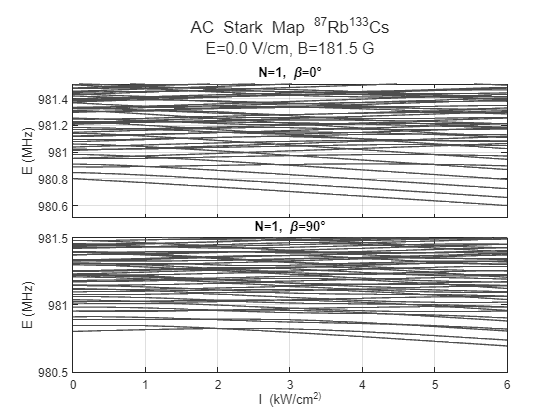

scalarACoffset = (Mol.a0/(2*C.e0*C.c))*xplot*F.scaling / C.h;
% scalarACoffset = 0;

N = Base.getStates("N");
figure(12); clf;
t = tiledlayout(2,1,TileSpacing="tight");

GSEnergy = squeeze(min(energyMap(1,:,:),[],'all')-scalarACoffset)'*1e-6;
nexttile(t); %beta=0
plot(xplot,squeeze(energyMap(1,:,N==1))*1e-6-GSEnergy, color=[1,1,1]*0.3);
ylabel(sprintf("E (MHz)"))
xticklabels([])
ylim([0,1]+980.5) %87Rb133CS
xlim([0,6])
title("N=1, \beta=0°")
% 
GSEnergy = squeeze(min(energyMap(2,:,:),[],'all')-scalarACoffset)'*1e-6;
nexttile(t); %beta=90
plot(xplot,squeeze(energyMap(2,:,N==1))*1e-6-GSEnergy, color=[1,1,1]*0.3); hold on;
ylabel(sprintf("E (MHz)"))
ylim([0,1]+980.5) %87Rb133CS
xlim([min(xplot),max(xplot)])
title("N=1, \beta=90°")

xlabel("I (kW/cm^2)")
title(t,sprintf("AC Stark Map %s",Mol.name))
subtitle(t, sprintf("E=%.1f V/cm, B=%.1f G", Fields.E.value,Fields.B.value))

## Diagonalise for varying polarisation angle

B.value = 181.5;
B.dir = [0,0,1];
B.scaling = 1e-4; %put B.value in Gauss, not Tesla

E.value = 0; %V/m
E.dir = [0,0,1];
E.scaling = 1e2;%put E.value in V/cm, not V/m

I.value = 2.35;
I.dir = [1,0,0];
thetas=linspace(0,90,31)*pi/180;
theta = thetas(1);
phi=0;
I.pol = round([0*theta;sin(theta)*exp(1i*phi);cos(theta)],6);
I.scaling = 1e7;%put I.value in kW/cm^2, not W/m^2

Fields.B = B;
Fields.E = E;
Fields.I = I;

Mol = RbCs;
Ham = Hamiltonian(Molecule = Mol, Fields=Fields, maxN=maxN);
H0 = Ham.hyperfine.total + E.value*E.scaling*Ham.dc_stark + B.value*B.scaling*Ham.zeeman;
Base = Ham.Basis;
nStates = Base.NStates;
st = Base.getStates("all");

x = thetas;
energyMap = nan(length(x),nStates);
statesMap = nan(length(x),nStates,nStates);
fprintf("Diagonalising - ")

Diagonalising - 

for k = 1:length(x)
    if mod(k,10)==1; fprintf("%d - ",k); end
    theta = thetas(k);
    phi=0;
    I.pol = round([0*theta;sin(theta)*exp(1i*phi);cos(theta)],6);
    H_ac = Ham.makeACStark(0,Mol.a2,st.N,st.mN,Field=I);
    H = H0 + I.value*I.scaling*H_ac;
    [V,D] = eig(full(H/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
    [d,sortIdx] = sort(real(D));
    energyMap(k,:)=d;        
    statesMap(k,:,:) = V(:,sortIdx);
end

1 - 11 - 21 - 31 - 

Finished

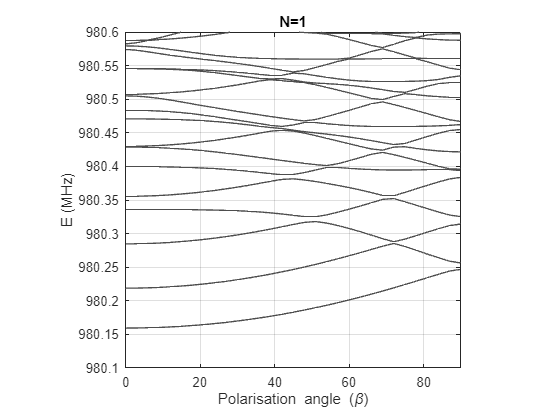

% scalarACoffset = (Mol.a0/(2*C.e0*C.c))*x*F.scaling / C.h;
scalarACoffset = 0;
GSEnergy = (min(energyMap,[],'all')-scalarACoffset)'*1e-6;

N = Base.getStates("N");
figure(12); clf;
t = tiledlayout("flow",TileSpacing="tight");
xplot=x*180/pi;
nexttile(t); %N=2 manifold
plot(xplot,energyMap(:,N==1)*1e-6-GSEnergy, color=[1,1,1]*0.3);
ylabel(sprintf("E (MHz)"))
% xticklabels([])
ylim([0.1,0.6]+980)
xlim([min(xplot),max(xplot)])
axis square
title("N=1")
xlabel("Polarisation angle (\beta)")

## Diagonalise for varying ellipticity

thetas=linspace(0,90,31)*pi/180;
phis=linspace(0,180,31)*pi/180;
theta = thetas(1);
phi=phis(1);

x = phis;
energyMap = nan(length(x),nStates);
statesMap = nan(length(x),nStates,nStates);
fprintf("Diagonalising - ")

Diagonalising - 

for k = 1:length(x)
    if mod(k,10)==1; fprintf("%d - ",k); end
    phi = phis(k);
    theta=thetas(1);
    I.pol = round([0*theta;sin(theta)*exp(1i*phi);cos(theta)],6);
    H_ac = Ham.makeACStark(0,Mol.a2,st.N,st.mN,Field=I);
    H = H0 + I.value*I.scaling*H_ac;
    [V,D] = eig(full(H/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
    [d,sortIdx] = sort(real(D));
    energyMap(k,:)=d;        
    statesMap(k,:,:) = V(:,sortIdx);
end

1 - 11 - 21 - 31 - 

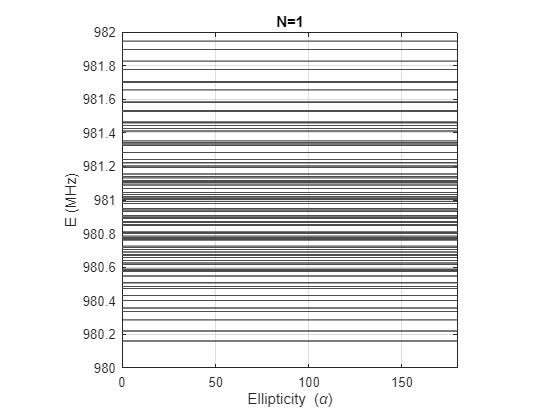

% scalarACoffset = (Mol.a0/(2*C.e0*C.c))*x*F.scaling / C.h;
scalarACoffset = 0;
GSEnergy = (min(energyMap,[],'all')-scalarACoffset)'*1e-6;

N = Base.getStates("N");
figure(12); clf;
t = tiledlayout("flow",TileSpacing="tight");
xplot=x*180/pi;
nexttile(t); %N=2 manifold
plot(xplot,energyMap(:,N==1)*1e-6-GSEnergy, color=[1,1,1]*0.3);
ylabel(sprintf("E (MHz)"))
% xticklabels([])
% ylim([0.1,0.6]+980)
xlim([min(xplot),max(xplot)])
axis square
title("N=1")
xlabel("Ellipticity (\alpha)")